% Clear screen
clear all
close all
clc

% Load keplar data
kepler_data=fitsread("kplr010001893-2011177032512_llc.fits","binarytable");

time_ = kepler_data{1};
data_ = kepler_data{4};

% Remove NaN data
data=data_(~isnan(data_));
time=time_(~isnan(data_));

data_N = length(data);

delta_t = (time(end)-time(1))/length(time)

delta_t = 0.0209


f_sample=1/delta_t;

f_sample = 47.7774

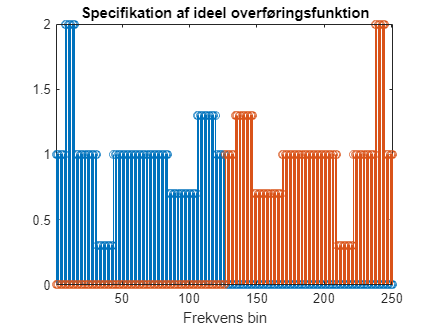

f_cutoff = f_sample / 2;
M = 250;

freq_resolution = f_sample / M;
freq_bin = f_cutoff / freq_resolution;
freq_bin_round = round(freq_bin);

H_left  = [1 ones(1,freq_bin_round) zeros(1,(M/2)-freq_bin_round)];
  H_left(32:43)=0.3;
  H_left(8:15)=2;
  H_left(85:105)=0.7;
  H_left(106:119)=1.3;
H_right = fliplr(H_left(2:end));

H = [H_left H_right];

figure(1); clf
stem([H_left zeros(1,M/2)])
xlabel('Frekvens bin')
axis([1 M+1 0 2])
hold on
stem([zeros(1,M/2+1) H_right])
title('Specifikation af ideel overføringsfunktion')

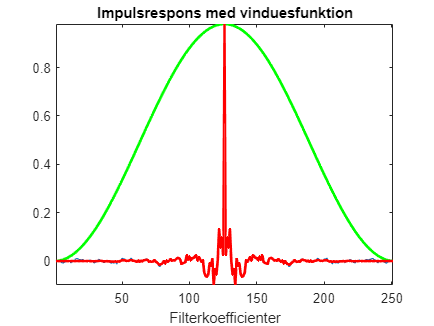


h = fftshift(real(ifft(H)));

figure(2); clf
plot(h)
xlabel('Filterkoefficienter')
axis([1 M+1 -inf inf])
hold on
title('Impulsrespons')


w_hanning = hanning(M+1)';
h_win = h.*w_hanning;
plot(w_hanning*max(abs(h)),'g','linewidth',2)
title('Impulsrespons og vindue')
plot(h_win,'r','linewidth',2)
title('Impulsrespons med vinduesfunktion')

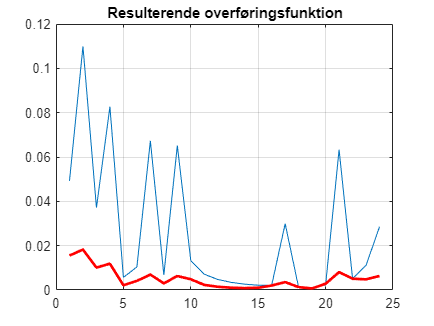


f_sample_round = round(f_sample);

H_without_win = fft(h,f_sample_round);
H_with_win = fft(h_win,f_sample_round);

figure(3); clf
plot(abs(H_without_win(1:f_sample_round/2)))
hold on
plot(abs(H_with_win(1:f_sample_round/2)),'r','linewidth',2)
grid on
title('Resulterende overføringsfunktion')

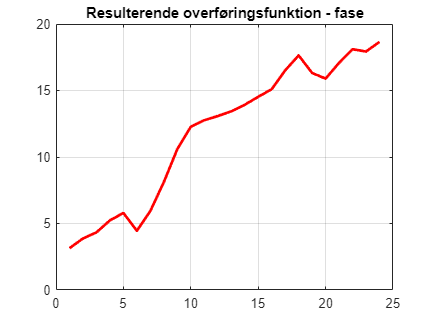



figure(4); clf
plot(unwrap(angle(H_with_win(1:f_sample_round/2))),'r','linewidth',2)
grid on
title('Resulterende overføringsfunktion - fase')